clc
clear 
close all

load Tchaikovsky.mat 

x = signal(:,1);

## Filtrado

hd = fir_kaiser_100;

y = filter(hd, x);


## Respuesta en el dominio del tiempo


% sound (y, Fs);


## Respuesta en el dominio de la frecuencia

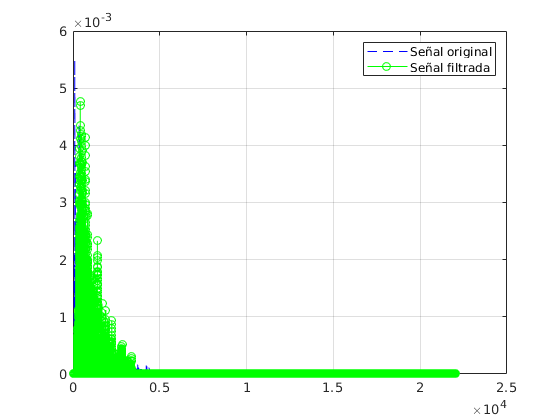

[f, m] = my_dft(x, Fs);
[fw, mw] = my_dft(y, Fs);

figure
plot(f, m, '--b')
hold on
plot(fw, mw, '-og')
hold off
grid on
legend('Señal original', 'Señal filtrada')